# **A simple method to s****eparat****e** **birds and insects in single-pol weather** **radar** 

**Rapha****ë****l Nussbaumer1****,*********,** **Baptiste Schmid1** **,** **Silke Bauer1** **and Felix Liechti1**

1 Swiss Ornithological Institute, Sempach, Switzerland 

* Correspondence: raphael.nussbaumer@vogelwarte.ch

## Introduction

This code accompagnes the publication: Nussbaumer, R.; Schmid, B.; Bauer, S.; Liechti, F. Technical a Gaussian Mixture Model to Separate Birds and Insects in Single-Polarization Weather Radar Data. *Remote Sens.* **2021**, *13*, 1989. [https://doi.org/10.3390/rs13101989](https://doi.org/10.3390/rs13101989)

It explains how the methodology is implemented, how the figure are produced and how the resulting dateset is exported (available on zenodo: [https://doi.org/10.5281/zenodo.3610184](https://doi.org/10.5281/zenodo.3610184))

## Abstract

Recent and archived data from weather radar networks are extensively used for the quantification of continent-wide bird migration patterns. While the process of discriminating birds from weather signals is well established, insect contamination is still a problem. We present a simple method combining two Doppler radar products within a Gaussian mixture model to estimate the proportions of birds and insects within a single measurement volume, as well as the density and speed of birds and insects. This method can be applied to any existing archives of vertical bird profiles, such as the European Network for the Radar surveillance of Animal Movement repository, with no need to recalculate the huge amount of original polar volume data, which often are not available.

## **Setup**

### **Load the data**

load('data/dc_corr')
load('coastlines.mat')

Define default color as viridis. Code can be downloadeded from [https://www.mathworks.com/matlabcentral/fileexchange/51986-perceptually-uniform-colormaps](https://www.mathworks.com/matlabcentral/fileexchange/51986-perceptually-uniform-colormaps)

if (exist('viridis'))
    set(0,'DefaultFigureColormap',viridis);
else
    web('https://www.mathworks.com/matlabcentral/fileexchange/51986-perceptually-uniform-colormaps')
end

### Determine windspeed at radar location

The U ([parmID=131](https://apps.ecmwf.int/codes/grib/param-db/?id=131)) and V ([parmID=132](https://apps.ecmwf.int/codes/grib/param-db/?id=132)) component of wind are downloaed from the ERA5 reanalysis ([https://doi.org/10.24381/cds.bd0915c6](https://doi.org/10.24381/cds.bd0915c6)) at pressure level (from 1000hPa to 550hPa), downloaded at the maximal resoluation (hourly and 0.25°x0.25°). See python file [ECMWF/script_ECMWF.py](http:///ECMWF/script_ECMWF.py) for more details on the download.

%ncdisp(file{1});
file={'./ECMWF/2018_pressure_1.nc','./ECMWF/2018_pressure_2.nc','./ECMWF/2018_pressure_3.nc','./ECMWF/2018_pressure_4.nc'};
wind.time = datenum('01-janv-2018'):1/24:datenum('31-dec-2018 23:00');
wind.latitude=flip(double(ncread(file{1},'latitude')));
wind.longitude=double(ncread(file{1},'longitude'));
wind.pressure=double([ncread(file{1},'level') ; ncread(file{2},'level') ; ncread(file{3},'level') ; ncread(file{4},'level') ]);
wind.alt = (1-(wind.pressure*100/101325).^(1/5.25588))/2.25577/10^(-5);
tmp_1 = permute(flip(ncread(file{1},'u'),2) , [2 1 4 3]);
tmp_2 = permute(flip(ncread(file{2},'u'),2) , [2 1 4 3]);
tmp_3 = permute(flip(ncread(file{3},'u'),2) , [2 1 4 3]);
tmp_4 = permute(flip(ncread(file{4},'u'),2) , [2 1 4 3]);
wind.u = cat(4,tmp_1,tmp_2,tmp_3,tmp_4); % m/s
tmp_1 = permute(flip(ncread(file{1},'v'),2) , [2 1 4 3]);
tmp_2 = permute(flip(ncread(file{2},'v'),2) , [2 1 4 3]);
tmp_3 = permute(flip(ncread(file{3},'v'),2) , [2 1 4 3]);
tmp_4 = permute(flip(ncread(file{4},'v'),2) , [2 1 4 3]);
wind.v = cat(4,tmp_1,tmp_2,tmp_3,tmp_4); % m/s
tmp_1 = permute(flip(ncread(file{1},'t'),2) , [2 1 4 3]);
tmp_2 = permute(flip(ncread(file{2},'t'),2) , [2 1 4 3]);
tmp_3 = permute(flip(ncread(file{3},'t'),2) , [2 1 4 3]);
tmp_4 = permute(flip(ncread(file{4},'t'),2) , [2 1 4 3]);
wind.t = cat(4,tmp_1,tmp_2,tmp_3,tmp_4); % K
clear tmp_* file

All three variables are linearly interpolated (time-space 4D) at each datapoint of the weather radar data. 

Fu = griddedInterpolant({wind.latitude,wind.longitude,datenum(wind.time),wind.alt},wind.u,'linear','linear');
Fv = griddedInterpolant({wind.latitude,wind.longitude,datenum(wind.time),wind.alt},wind.v,'linear','linear');
Ft = griddedInterpolant({wind.latitude,wind.longitude,datenum(wind.time),wind.alt},wind.t,'linear','linear');

for i_d=1:numel(dc)
    windu = permute(Fu({dc(i_d).lat,dc(i_d).lon,datenum(dc(i_d).time),dc(1).alt}),[3,4,1,2]);
    windv = permute(Fv({dc(i_d).lat,dc(i_d).lon,datenum(dc(i_d).time),dc(1).alt}),[3,4,1,2]);
    dc(i_d).wt = permute(Ft({dc(i_d).lat,dc(i_d).lon,datenum(dc(i_d).time),dc(1).alt}),[3,4,1,2]);
    dc(i_d).ws = windu + 1i*windv;
end

Export dataset and clear

clear wind Fu Fv
% save('data/dc_corr','dc','start_date','end_date','quantity','-v7.3')

### Compute airspeed and standar deviation `v_a` radial velocity `sdvvp`

v_a = nan(numel(dc(1).time), numel(dc(1).alt), numel(dc));
sdvvp = v_a;
for i_d=1:numel(dc)
    
    % Compute the n/s and e/w componenent of the flight speed
    % [-u,v] = pol2cart(deg2rad(dc(i_d).dd+90), dc(i_d).ff);
    % u =  dc(i_d).ff .* sind(dc(i_d).dd); % m/s | 0° is north and 90° is east. -> u is east (+) - west (-)
    % v = dc(i_d).ff .* cosd(dc(i_d).dd); % m/s  -> v is north (+) - south (-)
    % gs = u + 1i*v;
    gs =  dc(i_d).ff .* exp(deg2rad(mod(-dc(i_d).dd+90,360))*1i);
    
    % Remove data not cleaned for density (e.g. rain).
    id = isnan(dc(i_d).dens3) | dc(i_d).dens3==0;
    gs(id) = nan;
    sd_vvp = dc(i_d).sd_vvp;
    sd_vvp(id) = nan;
    
    v_a(:,:,i_d) = gs - dc(i_d).ws;
    sdvvp(:,:,i_d) = sd_vvp;
end

Plot airpseed and sdvvp histogram

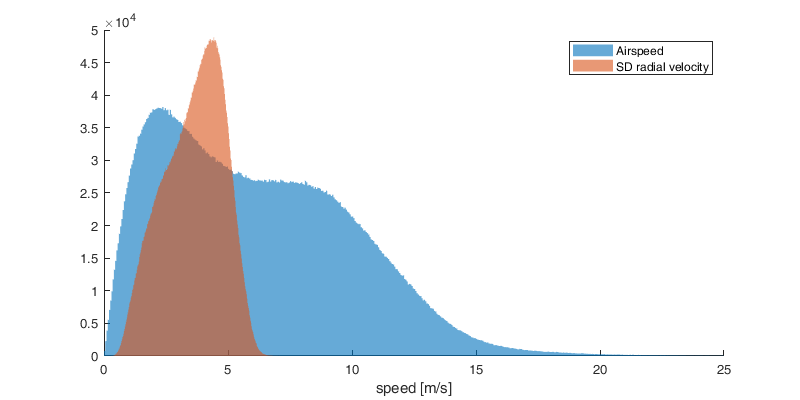

figure('position',[0 0 800 400]); hold on;
histogram(abs(v_a),'EdgeColor','none','DisplayName','Airspeed')
histogram(sdvvp,'EdgeColor','none','DisplayName','SD radial velocity')
legend; xlabel('speed [m/s]'); xlim([0 25])

## Model fitting

### Compute empirical PDF and fit with a mixture of Gaussian

Avoid to recompute the `gmfit` and the `ampli* `and` f*`

load('data/insect_removal')

Define variable used later

t =  datenum(dc(1).time)-datenum(dc(1).time(1));
nmonth = 12;
tmonth = linspace(t(1), t(end), nmonth+1);
tweek = t(1):7:t(end);
nweek = numel(tweek);
tmonth_mid = tmonth(1:end-1)+diff(tmonth)/2;
tmonth_mid_rep = [tmonth_mid-365 tmonth_mid tmonth_mid+365]

France and German radar

id_de = [false; true(15,1); false(21,1)];
id_fr = [false(16,1); true(19,1); false(2,1)];

Build the vector of data removing nan value

X = [abs(v_a(:)) sdvvp(:)];
X = X(~any(isnan(X),2),:);

Fit a kernel density function

[xi1, xi2] = meshgrid(0:.25:15,0:.1:7);
ft = reshape(ksdensity(X, [xi1(:), xi2(:)]),size(xi1));
ft = ft./sum(ft(:));

Fit Gaussian mixture model with two components

S.mu = [8 4 ; 2.5 3];
S.Sigma = cat(3,[11 -1 ; -1 1], [2 0.1 ; 0.1 1]);
S.ComponentProportion = [0.7 0.3];
rng('default')
gmfit = fitgmdist(X,2,'Replicates',1,'Start',S);

Compute the normalized pdf of each gaussian

gm1 = gmdistribution(gmfit.mu(1,:), gmfit.Sigma(:,:,1));
f_1 = reshape(pdf(gm1,[xi1(:) xi2(:)]),size(xi1));
f_1 = f_1./sum(f_1(:));
gm2 = gmdistribution(gmfit.mu(2,:), gmfit.Sigma(:,:,2));
f_2 = reshape(pdf(gm2,[xi1(:) xi2(:)]),size(xi1));
f_2 = f_2./sum(f_2(:));

Plot the fitted pdf

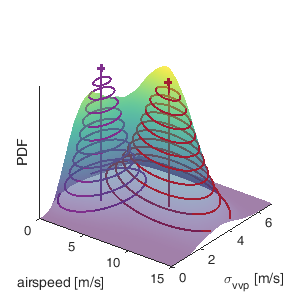

figure('position',[0 0 300 300]); hold on; hold on
% plot(xi1(islocalmax(ft)&islocalmax(ft,2)), xi2(islocalmax(ft)&islocalmax(ft,2)),'.r')
surf(xi1, xi2, ft,'FaceAlpha',0.8)
[~,p1]=contour3(xi1, xi2, gmfit.ComponentProportion(1)*f_1*1.2,10,'Color',[251 193 135]/255,'linewidth',1.5);
[~,id_max] = max(f_1(:));
plot3(xi1(id_max),xi2(id_max),gmfit.ComponentProportion(1)*f_1(id_max),'+','Color',[251 193 135]/255,'LineWidth',2,'MarkerSize',6)
plot3([xi1(id_max) xi1(id_max)],[xi2(id_max) xi2(id_max)], [0 gmfit.ComponentProportion(1)*f_1(id_max)],'Color',[251 193 135]/255,'LineWidth',1.5 )
[~,p2]=contour3(xi1, xi2, gmfit.ComponentProportion(2)*f_2*.85,10,'Color',[33 32 85]/255,'linewidth',1.5);
[~,id_max] = max(f_2(:));
plot3(xi1(id_max),xi2(id_max),gmfit.ComponentProportion(2)*f_2(id_max),'+','Color',[33 32 85]/255,'LineWidth',2,'MarkerSize',6)
plot3([xi1(id_max) xi1(id_max)],[xi2(id_max) xi2(id_max)], [0 gmfit.ComponentProportion(2)*f_2(id_max)],'Color',[33 32 85]/255,'LineWidth',1.5 )
axis tight;shading interp; view(37,31)
xlabel('airspeed [m/s]'); ylabel('\sigma_{vvp} [m/s]'); zlabel('PDF')
%legend([p1 p2], 'Multi-normal corresponding to bird','Multi-normal corresponding to insect')
Ax = gca; Ax.ZAxis.TickValues=[];
colormap(gca,viridis) %colormap(gca,1-(1-viridis)/1.2) %

Display parameters of the gaussian

disp(gmfit.mu)

    7.9599    4.1032
    2.6119    2.7799



disp(gmfit.Sigma)


(:,:,1) =

   11.5652   -1.1574
   -1.1574    0.9159


(:,:,2) =

    1.8133    0.1578
    0.1578    1.0829



Plot figure as a comparison with threashold

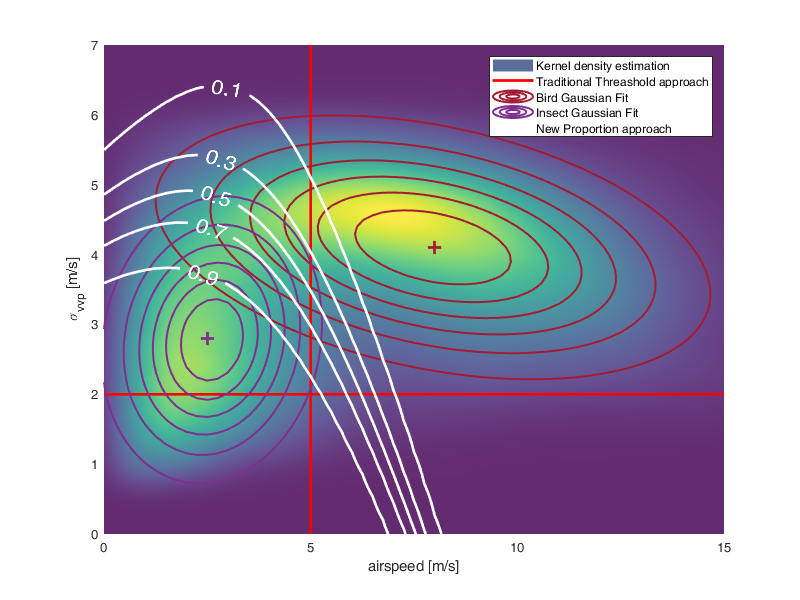

figure('position',[0 0 800 600]); hold on; hold on
h(1)=pcolor(xi1(1,:), xi2(:,1), ft./max(ft(:)));
h(2)=plot([0 15],[2 2],'r','linewidth',2);
plot([5 5],[0 7],'r','linewidth',2);
[~,h(3)]=contour(xi1, xi2, f_1,6,'Color',[251 193 135]/255,'LineWidth',1.5);
[~,id_max] = max(f_1(:)); plot(xi1(id_max),xi2(id_max),'+','Color',[251 193 135]/255,'LineWidth',2,'MarkerSize',10)
[~,h(4)]=contour(xi1, xi2, f_2,6,'Color',[33 32 85]/255,'LineWidth',1.5);
[~,id_max] = max(f_2(:)); plot(xi1(id_max),xi2(id_max),'+','Color',[33 32 85]/255,'LineWidth',2,'MarkerSize',10)
[C,h(5)]=contour(xi1, xi2, f_2./(f_1+f_2),.1:.2:.9,'w','ShowText','on','LineWidth',2);
clabel(C,h(5),'FontSize',15,'Color','w','LabelSpacing',500,'FontWeight','bold')
axis tight;shading interp;
xlabel('airspeed [m/s]'); ylabel('\sigma_{vvp} [m/s]');
legend(h,{'Kernel density estimation','Traditional Threashold approach','Bird Gaussian Fit','Insect Gaussian Fit','New Proportion approach'})
colormap(gca,1-(1-viridis)/1.2) %colormap(gca,viridis)

### Compute amplitude ratio 

#### Compute amplitude ratio over time 

amplit = nan(1,nmonth);
ftime = nan(size(xi1,1), size(xi1,2),nmonth);
for i=1:nmonth
    id = tmonth(i)<t & tmonth(i+1)>t;
    X = [reshape(abs(v_a(id,:,:)),[],1),reshape(sdvvp(id,:,:),[],1)];
    X = X(~any(isnan(X),2),:);
    if ~isempty(X)
        ftime(:,:,i) = reshape(ksdensity(X, [xi1(:), xi2(:)]),size(xi1));
        ftime(:,:,i) = ftime(:,:,i)./sum(sum(ftime(:,:,i)));
        mismatch = @(alpha) ( alpha.*f_1 + (1-alpha).*f_2);
        amplit(i) = fminsearch(@(alpha) sum(sum((ftime(:,:,i)-mismatch(alpha)).^2)) , 0.5 );
    end
end
amplit(amplit==0)=nan;

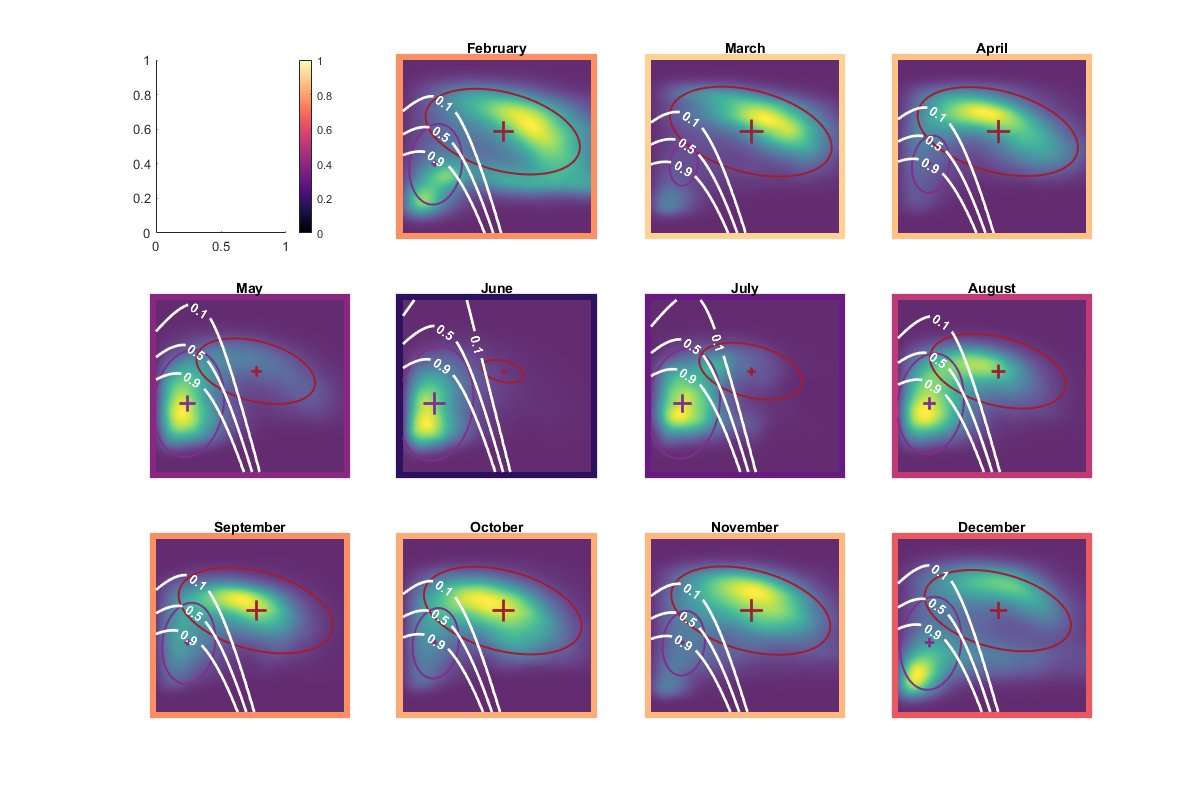

figure('position',[0 0 1200 800]); hold on;
c_map = magma;
for i=1:nmonth
    ax=subplot(3,4,i); hold on
    if i==1
        colorbar
        colormap(gca,magma)
    else
        id = tmonth(i)<t & tmonth(i+1)>t;
        pcolor(xi1(1,:), xi2(:,1), ftime(:,:,i)./max(max(ftime(:,:,i))))
        contour(xi1, xi2, amplit(i)*f_1,[0.0002 0.01],'Color',[251 193 135]/255,'LineWidth',1.5);
        [~,id_max] = max(f_1(:));
        plot(xi1(id_max),xi2(id_max),'+','Color',[251 193 135]/255,'LineWidth',2,'MarkerSize',amplit(i)*20)
        contour(xi1, xi2, (1-amplit(i))*f_2,[0.0002 0.01],'Color',[33 32 85]/255,'LineWidth',1.5);
        [~,id_max] = max(f_2(:));
        plot(xi1(id_max),xi2(id_max),'+','Color',[33 32 85]/255,'LineWidth',2,'MarkerSize',(1-amplit(i))*20)
        [C,h]=contour(xi1, xi2, (1-amplit(i))*f_2./(amplit(i)*f_1+(1-amplit(i))*f_2),[.1 .5 .9],'w','ShowText','on','LineWidth',2);
        clabel(C,h,'Color','w','LabelSpacing',500,'FontWeight','bold')
        axis tight;shading interp;
        title(month(median(dc(1).time(id)),'name'))
        %xlabel('airspeed [m/s]'); ylabel('\sigma_{vvp} [m/s]');
        colormap(gca,1-(1-viridis)/1.2)
        
        box on
        i_c = ceil(amplit(i)*size(c_map,1));
        ax.XColor = c_map(i_c,:);
        ax.YColor = c_map(i_c,:);
        ax.LineWidth=10;
        ax.XTick=[]; ax.YTick=[];
    end
end

#### Compute amplitude ratio over space

amplir = nan(1,numel(dc));
fradar = nan(size(xi1,1), size(xi1,2),numel(dc));
for i_d=1:numel(dc)-1
    X = [reshape(abs(v_a(:,:,i_d)),[],1),reshape(sdvvp(:,:,i_d),[],1)];
    X = X(~any(isnan(X),2),:);
    if ~isempty(X)
        fradar(:,:,i_d) = reshape(ksdensity(X, [xi1(:), xi2(:)]),size(xi1));
        fradar(:,:,i_d) = fradar(:,:,i_d)./sum(sum(fradar(:,:,i_d)));
        mismatch = @(alpha) ( alpha.*f_1 + (1-alpha).*f_2);
        amplir(i_d) = fminsearch(@(alpha) sum(sum((fradar(:,:,i_d)-mismatch(alpha)).^2)) , 0.5 );
    end
end
amplir(amplir==0)=nan;

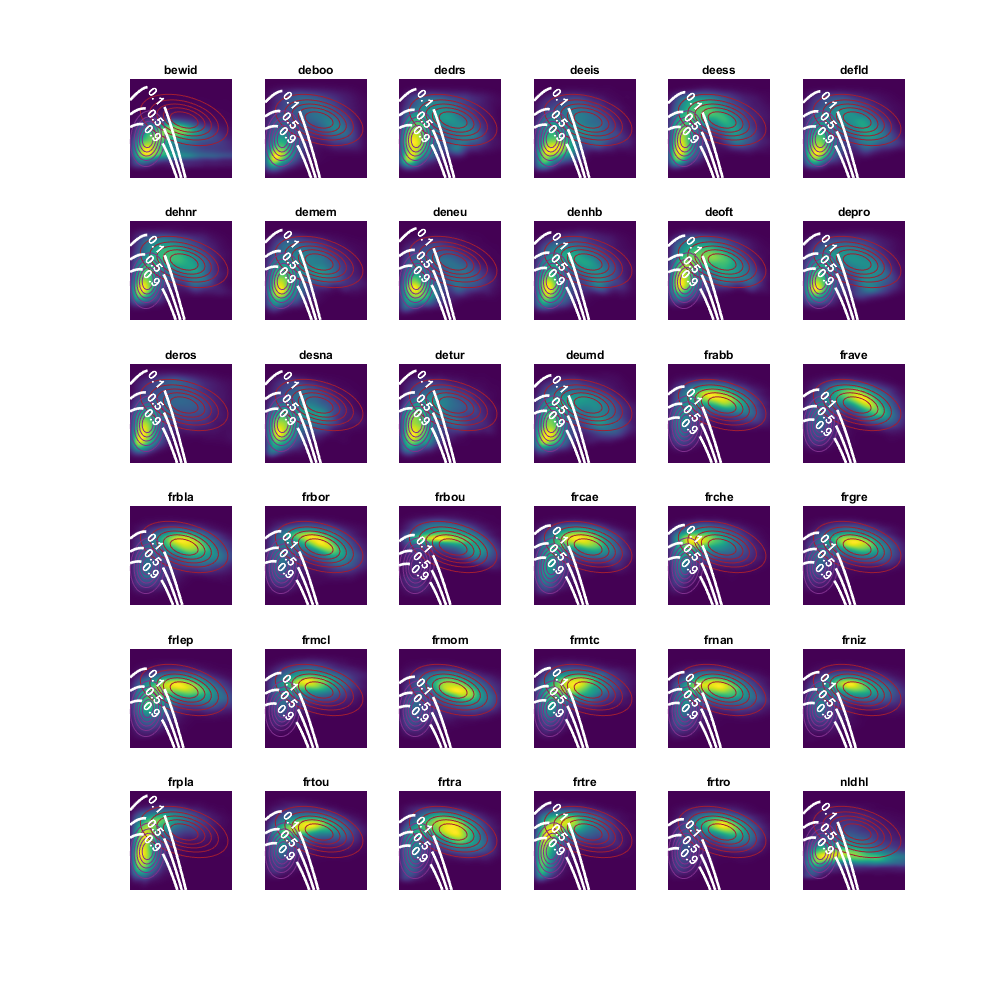

figure('position',[0 0 1000 1000]); hold on;
for i_d=1:numel(dc)-1
    ax=subplot(6,6,i_d); hold on
    pcolor(xi1(1,:), xi2(:,1), fradar(:,:,i_d)./max(max(fradar(:,:,i_d))))
    contour(xi1, xi2, amplir(i_d)*f_1,5,'Color',[251 193 135]/255);
    contour(xi1, xi2, (1-amplir(i_d))*f_2,5,'Color',[33 32 85]/255);
    [C,h]=contour(xi1, xi2, (1-amplir(i_d))*f_2./(amplir(i_d)*f_1+(1-amplir(i_d))*f_2),[.1 .5 .9],'w','ShowText','on','LineWidth',2);
    clabel(C,h,'Color','w','LabelSpacing',500,'FontWeight','bold')
    axis tight;shading interp; title(dc(i_d).name)
    ax.XTick=[]; ax.YTick=[];
    %xlabel('airspeed [m/s]'); ylabel('\sigma_{vvp} [m/s]');
end

#### Compute amplitude ratio over altitude

amplia = nan(1,25);
falt = nan(size(xi1,1), size(xi1,2), 25);
for i=1:25
    X = [reshape(abs(v_a(:,i,:)),[],1),reshape(sdvvp(:,i,:),[],1)];
    X = X(~any(isnan(X),2),:);
    if ~isempty(X)
        falt(:,:,i) = reshape(ksdensity(X, [xi1(:), xi2(:)]),size(xi1));
        falt(:,:,i) = falt(:,:,i)./sum(sum(falt(:,:,i)));
        mismatch = @(alpha) ( alpha.*f_1 + (1-alpha).*f_2);
        amplia(i) = fminsearch(@(alpha) sum(sum((falt(:,:,i)-mismatch(alpha)).^2)) , 0.5 );
    end
end
amplia(amplia==0)=nan;

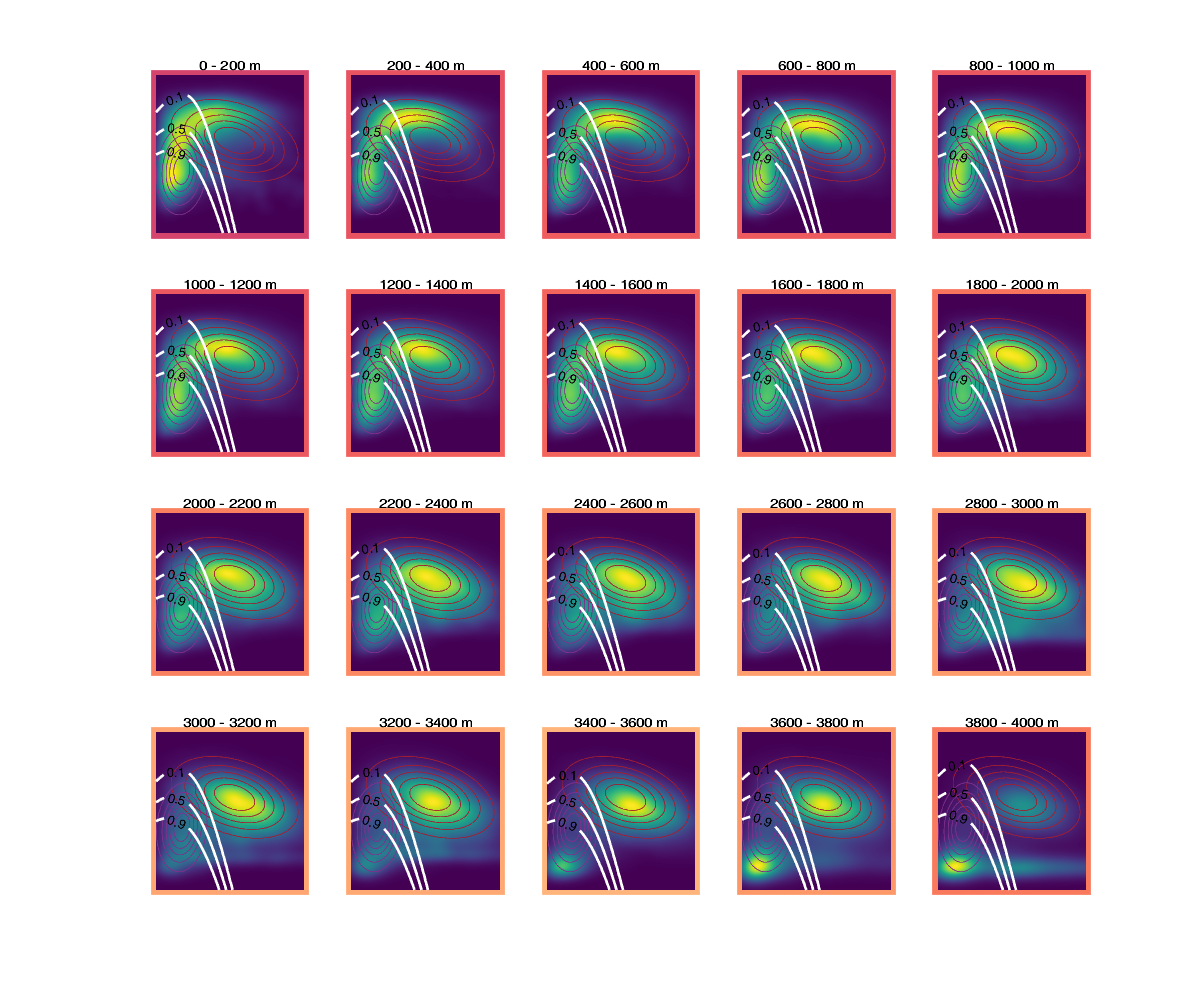

figure('position',[0 0 1200 1000]); hold on; c_map = magma;
for i=1:20
    ax=subplot(4,5,i); hold on
    
    pcolor(xi1(1,:), xi2(:,1), falt(:,:,i)./max(max(falt(:,:,i))))
    contour(xi1, xi2, amplia(i)*f_1,5,'Color',[251 193 135]/255);
    contour(xi1, xi2, (1-amplia(i))*f_2,5,'Color',[33 32 85]/255);
    contour(xi1, xi2, (1-amplia(i))*f_2./(amplia(i)*f_1+(1-amplia(i))*f_2),[.1 .5 .9],'w','ShowText','on','LineWidth',2)
    axis tight;shading interp; xticks([]); yticks([])
    %xlabel('airspeed [m/s]'); ylabel('\sigma_{vvp} [m/s]');
    title([num2str(dc(1).alt(i)-100) ' - ' num2str(dc(1).alt(i)+100) ' m'])
    
    box on
    i_c = ceil(amplia(i)*size(c_map,1));
    ax.XColor = c_map(i_c,:);
    ax.YColor = c_map(i_c,:);
    ax.LineWidth=8;
    ax.XTick=[]; ax.YTick=[];
end

#### Compute amplitude ratio per radar and month

ampliall = nan(nmonth,numel(dc));
fall = nan(size(xi1,1), size(xi1,2), nweek, numel(dc));
nall = nan(nmonth,numel(dc));
for i=1:nmonth
    id = tmonth(max(1,i-1))<t & tmonth(min(nweek,i+2))>t;
    for i_d=1:numel(dc)
        X = [reshape(abs(v_a(id,:,i_d)),[],1),reshape(sdvvp(id,:,i_d),[],1)];
        X = X(~any(isnan(X),2),:);
        nall(i,i_d) = size(X,1);
        if ~isempty(X)
            fall(:,:,i,i_d) = reshape(ksdensity(X, [xi1(:), xi2(:)]),size(xi1));
            fall(:,:,i,i_d) = fall(:,:,i,i_d)./sum(sum(fall(:,:,i,i_d)));
            mismatch = @(alpha) ( alpha.*f_1 + (1-alpha).*f_2);
            ampliall(i,i_d) = fminbnd(@(alpha) sum(sum((fall(:,:,i,i_d)-mismatch(alpha)).^2)) , 0, 1 );
        end
    end
end
ampliall(ampliall==0)=nan;

i_d = find(strcmp({dc.name}, 'dedrs'));

% for i_d=1:numel(dc)
    figure('position',[0 0 1200 800]); hold on;
    c_map = magma;
    for i=1:nmonth
        if i==1
            ax=subplot(3,4,i); hold on
            title(dc(i_d).name)
            h = worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);
            setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
            geoshow('landareas.shp', 'FaceColor', [77 77 77]./255);
            scatterm([dc.lat], [dc.lon], 60,'ok', 'filled');
            scatterm(dc(i_d).lat, dc(i_d).lon, 120,'or','filled');
        elseif all(all(isnan(fall(:,:,i,i_d))))
            %title(month(median(dc(1).time(id)),'name'))
        else
            ax=subplot(3,4,i); hold on
            id = tmonth(i)<t & tmonth(i+1)>t;
            pcolor(xi1(1,:), xi2(:,1), fall(:,:,i,i_d)./max(max(fall(:,:,i,i_d))))
            contour(xi1, xi2, ampliall(i,i_d)*f_1,[0.0002 0.01],'Color',[251 193 135]/255,'LineWidth',1.5);
            [~,id_max] = max(f_1(:));
            plot(xi1(id_max),xi2(id_max),'+','Color',[251 193 135]/255,'LineWidth',2,'MarkerSize',ampliall(i,i_d)*20)
            contour(xi1, xi2, (1-ampliall(i,i_d))*f_2,[0.0002 0.01],'Color',[33 32 85]/255,'LineWidth',1.5);
            [~,id_max] = max(f_2(:));
            plot(xi1(id_max),xi2(id_max),'+','Color',[33 32 85]/255,'LineWidth',2,'MarkerSize',(1-ampliall(i,i_d))*20)
            [C,h]=contour(xi1, xi2, (1-ampliall(i,i_d))*f_2./(ampliall(i,i_d)*f_1+(1-ampliall(i,i_d))*f_2),[.1 .5 .9],'w','ShowText','on','LineWidth',2);
            clabel(C,h,'Color','w','LabelSpacing',500,'FontWeight','bold')
            axis tight;shading interp;
            title(month(median(dc(1).time(id)),'name'))
            %xlabel('airspeed [m/s]'); ylabel('\sigma_{vvp} [m/s]');
            %xticks([]); yticks([]);
            colormap(gca,1-(1-viridis)/1.2)
            
            box on
            i_c = ceil(ampliall(i,i_d)*size(c_map,1));
            ax.XColor = c_map(i_c,:);
            ax.YColor = c_map(i_c,:);
            ax.LineWidth=10;
            ax.XTick=[]; ax.YTick=[];
        end
    end
    % saveas(gcf,['C:\Users\rnussba1\switchdrive\Paper\InsectWR\figure\PerRadar\' dc(i_d).name '.png']) % ,'-dpdf -painters epsFig'
% end


Map the amplitude ratio per month and radar

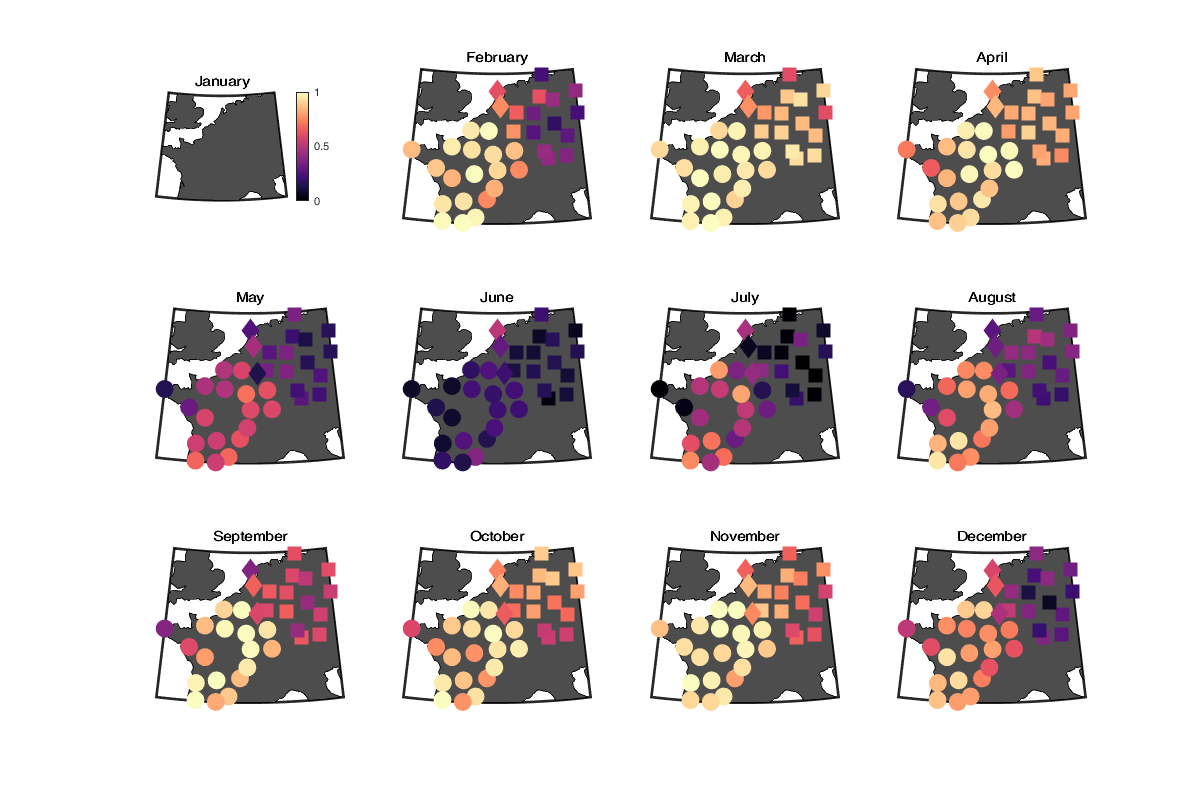

figure('position',[0 0 1200 800]);
for i=1:nmonth
    id = tmonth(i)<t & tmonth(i+1)>t;
    subplot(3,4,i);title(month(median(dc(1).time(id)),'name'))
    h = worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    geoshow('landareas.shp', 'FaceColor', [77 77 77]./255);
    scatterm([dc(id_de).lat], [dc(id_de).lon], 180,ampliall(i,id_de),'s', 'filled');
    scatterm([dc(id_fr).lat], [dc(id_fr).lon], 180, ampliall(i,id_fr),'o','filled');
    scatterm([dc(~id_fr&~id_de).lat]', [dc(~id_fr&~id_de).lon]', 180, ampliall(i,~id_fr&~id_de)','d','filled');
    caxis([0 1])
    colormap(gca,magma)
    if i==1
        colorbar
    end
end

### Temporal interpolation of the amplitude ratio 

warning('off')
ampliall(ampliall==0)=nan;
ampliall_mean =repmat(nanmean(ampliall,2),1,37);
ampliall_fil = ampliall;
ampliall_fil(isnan(ampliall_fil))=ampliall_mean(isnan(ampliall_fil));
ampliall_rep = [ampliall_fil; ampliall_fil; ampliall_fil];

for i_d=1:numel(dc)
    % i_c = ceil((dc(i_d).lat-43.5)/(54.2-43.5)*size(c_map,1));
    ti(:,i_d) = interp1( tmonth_mid_rep, ampliall_rep(:,i_d), t, 'pchip');
end

Figure

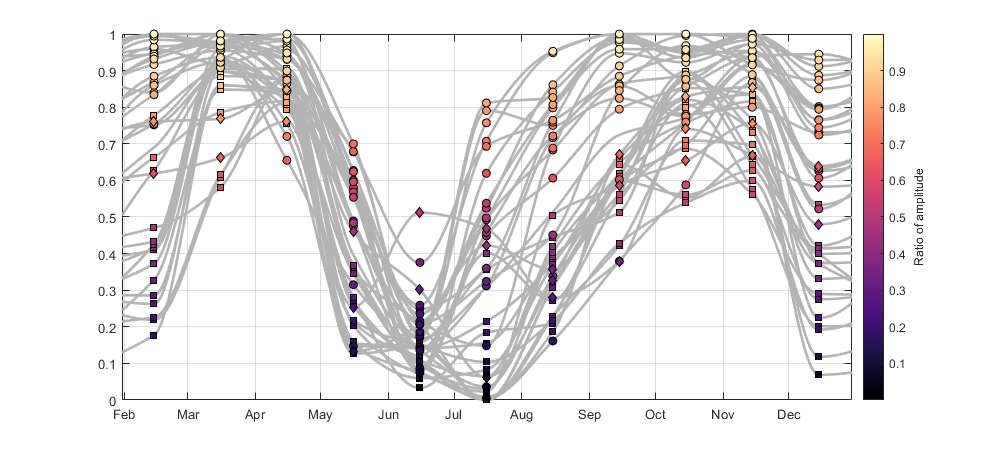

figure('position',[0 0 1000 450]); hold on;
plot( t, ti,'Color',[.7 .7 .7],'LineWidth',2);
scatter(repmat(tmonth_mid',sum(id_de),1), reshape(ampliall(:,id_de),1,[])',[],reshape(ampliall(:,id_de),1,[])', 's','filled','MarkerEdgeColor','k');
scatter(repmat(tmonth_mid',sum(id_fr),1), reshape(ampliall(:,id_fr),1,[])',[],reshape(ampliall(:,id_fr),1,[])', 'o','filled','MarkerEdgeColor','k');
scatter(repmat(tmonth_mid',sum(~id_fr&~id_de),1), reshape(ampliall(:,~id_fr&~id_de),1,[])',[],reshape(ampliall(:,~id_fr&~id_de),1,[])', 'd','filled','MarkerEdgeColor','k');
ylim([0 1]); xlim([31 365]); datetick('x','keeplimits');
c=colorbar;c.Label.String='Ratio of amplitude';
box on; grid on
colormap(gca,magma)

### Separation of insect and weather

gaussian = @(mu,sigma,x) exp(-((x-mu)/sigma).^2/2);
skewedgaussian = @(mu,sigma,alpha,x) 2*gaussian(mu,sigma,x).*normcdf(alpha*(x-mu)/sigma);

funall= @(A1,m1,s1,a1,A2,m2,s2,a2,x) (A1*skewedgaussian(m1,s1,a1,x) + A2*(skewedgaussian(m2,s2,a2,x)+skewedgaussian(m2+365,s2,a2,x)));
funratio = @(A1,m1,s1,a1,A2,m2,s2,a2,x) A1*skewedgaussian(m1,s1,a1,x)./(A1*skewedgaussian(m1,s1,a1,x) + A2*(skewedgaussian(m2,s2,a2,x)+skewedgaussian(m2+365,s2,a2,x)));
parmbird0=[0.9,365/2,365/15,0];
parminsect0=[0.1,0,365/15,0];
parmall0=[parmbird0 parminsect0];

for i_d=1:numel(dc)
    [xData, yData] = prepareCurveData( tmonth_mid, 1-ampliall_fil(:,i_d) );
    fitresult{i_d} = fit( xData, yData, funall,...
        'StartPoint', parmall0, ...
        'Lower', [.5,  50,  5, -5, .01, -15,  5, -5], ...
        'Upper', [ 1, 150,100,  5, 1,   50, 50,  5]);
    % A1, m1, s1, a1, A2,   m2, s2, a2
end

Figure

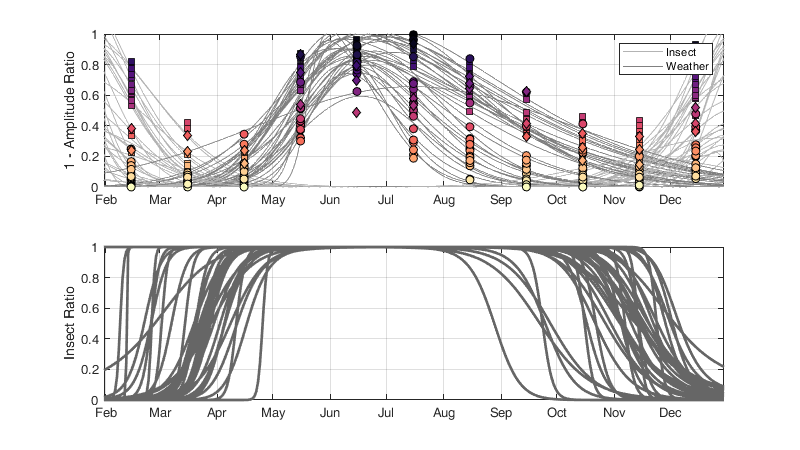

figure('position',[0 0 800 450]);
subplot(2,1,1); hold on;
for i_d=1:numel(dc)
    i_c = ceil((dc(i_d).lat-43.5)/(54.2-43.5)*size(parula,1));
    plot( 1:365, fitresult{i_d}.A2*skewedgaussian(fitresult{i_d}.m2,fitresult{i_d}.s2,fitresult{i_d}.a2,1:365),'Color',[.7 .7 .7]);
    plot( 1:365, fitresult{i_d}.A1*skewedgaussian(fitresult{i_d}.m1,fitresult{i_d}.s1,fitresult{i_d}.a1,1:365),'Color',[.5 .5 .5]);
    plot( 1:365, fitresult{i_d}.A2*skewedgaussian(fitresult{i_d}.m2+365,fitresult{i_d}.s2,fitresult{i_d}.a2,1:365),'Color',[.7 .7 .7]);
end
scatter(repmat(tmonth_mid',sum(id_de),1), 1-reshape(ampliall(:,id_de),1,[])',[],reshape(ampliall(:,id_de),1,[])', 's','filled','MarkerEdgeColor','k');
scatter(repmat(tmonth_mid',sum(id_fr),1), 1-reshape(ampliall(:,id_fr),1,[])',[],reshape(ampliall(:,id_fr),1,[])', 'o','filled','MarkerEdgeColor','k');
scatter(repmat(tmonth_mid',sum(~id_fr&~id_de),1), 1-reshape(ampliall(:,~id_fr&~id_de),1,[])',[],reshape(ampliall(:,~id_fr&~id_de),1,[])', 'd','filled','MarkerEdgeColor','k')
datetick('x','keeplimits');
ylim([0 1]); xlim([31 365]); datetick('x','keeplimits');
box on; grid on; legend('Insect','Weather')
ylabel('1 - Amplitude Ratio'); colormap(gca,magma)
subplot(2,1,2); hold on;
for i_d=1:numel(dc)
    i_c = ceil((dc(i_d).lat-43.5)/(54.2-43.5)*size(parula,1));
    plot( 1:365, funratio(fitresult{i_d}.A1,fitresult{i_d}.m1,fitresult{i_d}.s1,fitresult{i_d}.a1,fitresult{i_d}.A2,fitresult{i_d}.m2,fitresult{i_d}.s2,fitresult{i_d}.a2,1:365),'Color',[.4 .4 .4],'LineWidth',2);
end
datetick('x','keeplimits');ylim([0 1]); xlim([31 365]); grid on; box on
ylabel('Insect Ratio'); 

### Correction for bird and insect speed

We can used the value fitted on the gaussians which informs us on the mean and std airspeed of insect and bird

Define airspeed range

as=-5:0.05:25;

Compute the corresponding pdf for instect and bird

pdfB = normpdf(as,gmfit.mu(1,1), sqrt(gmfit.Sigma(1,1,1)));
pdfI = normpdf(as,gmfit.mu(2,1), sqrt(gmfit.Sigma(1,1,2)));

Plot the pdfs

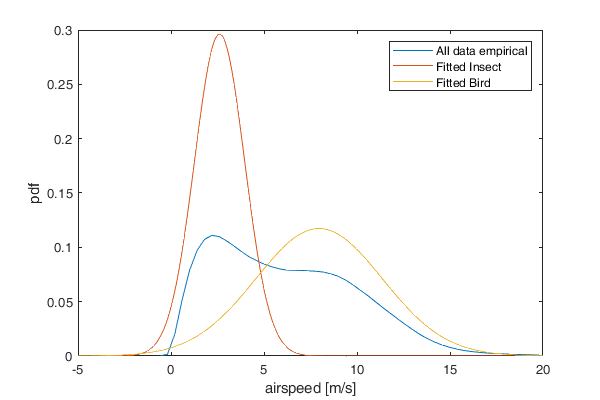

figure('position',[0 0 600 400]); hold on;
ksdensity(abs(v_a(:)))
plot(as,pdfI,'DisplayName','Fitted Insect');
plot(as,pdfB,'DisplayName','Fitted Bird');
xlabel('airspeed [m/s]'); ylabel('pdf')
box on; xlim([-5 20])
l=legend(); l.String{1} ='All data empirical';

Test for synthetic case

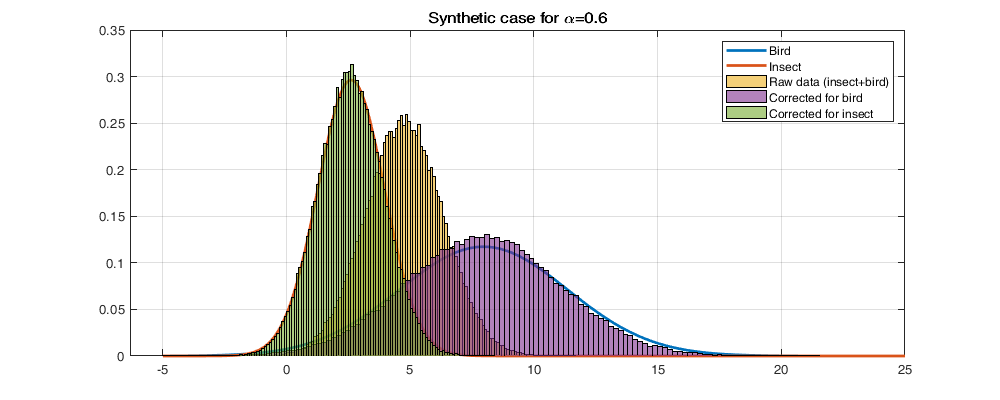

alpha0 = 0.6;

XI = normrnd(gmfit.mu(2,1), sqrt(gmfit.Sigma(1,1,2)),100000,1);
XB = normrnd(gmfit.mu(1,1), sqrt(gmfit.Sigma(1,1,1)),100000,1);
%XI = normrnd(gmfit.mu(1,1), 2.5,1000,1);
%XB = normrnd(gmfit.mu(2,1), 2.5,1000,1);
X = alpha0*XI + (1-alpha0)*XB;

% fg = @(mu,sigma,x) exp(-((x-mu)/sigma).^2/2);
% fb = @(b,x,alpha) fg(gmfit.mu(1,1),sqrt(gmfit.Sigma(1,1,1)),b) .* fg((1-alpha)*b+alpha*gmfit.mu(2,1), sqrt(gmfit.Sigma(1,1,2)),x);
% cb = @(x,alpha,r) integral( @(b) fb(b,x,alpha),-Inf,r) ./ integral( @(b) fb(b,x,alpha),-Inf,Inf);
% fsample = @(x,alpha) fsolve( @(r) abs(cb(x,alpha,r)-rand()), 10);
% fsample(X,alpha0)

% m1 = gmfit.mu(1,1);
% s1 = gmfit.Sigma(1,1,1);
% m2 = @(alpha,x) (x-alpha*gmfit.mu(2,1))/(1-alpha);
% s2 = @(alpha) gmfit.Sigma(1,1,2)/(1-alpha)^2;
% m12 = @(alpha,x) (m1*s2(alpha)+m2(alpha,x)*s1)/(s1*s2(alpha));
% s12 = @(alpha) (s1*s2(alpha))/(s1+s2(alpha));
% pdf12 = @(alpha,x) normpdf(as,m12(alpha,x),sqrt(s12(alpha)));
% rnd12 = @(alpha,x) normrnd(m12(alpha,x),sqrt(s12(alpha)),1);

pBsX = pdfB .* normpdf(X,alpha0.* gmfit.mu(2,1) + (1-alpha0)*as, sqrt(gmfit.Sigma(1,1,2)));
pBsX = pBsX./sum(pBsX,2);
[~,id] = min(abs(cumsum(pBsX,2) - rand(numel(X),1)),[],2);

% figure; hold on;
% tmp = cumsum(pBsX'./sum(pBsX'));
% plot(as,tmp)
% tmp = fb(as,X,alpha0);
% plot(as,cumsum(tmp)./sum(tmp))
% for i=1:numel(as)
%     plot(as(i),cb(X,alpha0,as(i)),'.k')
% end
%plot(normpdf(as,m2(alpha0,X),sqrt(s2(alpha0))))

%plot(normpdf(as,m2(alpha0,X),sqrt(s2(alpha0))))
%plot(normpdf(X,alpha0.* gmfit.mu(2,1) + (1-alpha0)*as, sqrt(gmfit.Sigma(1,1,2))))

Xcorr = as(id)+median(diff(as))*(rand(size(id'))-.5);
% Xcorr = X .* (1 - alpha0 + sqrt(gmfit.Sigma(1,1,2))/sqrt(gmfit.Sigma(1,1,1)).*alpha0) + (gmfit.mu(2,1) - gmfit.mu(1,1)*sqrt(gmfit.Sigma(1,1,2))/sqrt(gmfit.Sigma(1,1,1)) ).*alpha0;
%Xcorr = X*(1-alpha0+4.1/2.8*alpha0) + (8 - 2.6*4.1/2.8).*alpha0;


pIsX = pdfI .* normpdf(X,(1-alpha0).* gmfit.mu(1,1) + alpha0*as, sqrt(gmfit.Sigma(1,1,1)));
pIsX = pIsX./sum(pIsX,2);
[~,id] = min(abs(cumsum(pIsX,2) - rand(numel(X),1)),[],2);
XcorrI = as(id)+median(diff(as))*(rand(size(id'))-.5);

figure('position',[0 0 1000 400]); hold on;
plot(as,pdfB,'DisplayName','Bird','linewidth',2);
plot(as,pdfI,'DisplayName','Insect','linewidth',2);
histogram(X,'Normalization','pdf')
histogram(Xcorr,'Normalization','pdf')
histogram(XcorrI,'Normalization','pdf')
l=legend(); l.String{3}='Raw data (insect+bird)'; l.String{4}='Corrected for bird'; l.String{5}='Corrected for insect';
box on;  grid on; title(['Synthetic case for \alpha=' num2str(alpha0)])

Test on v_a (not the full dataset)

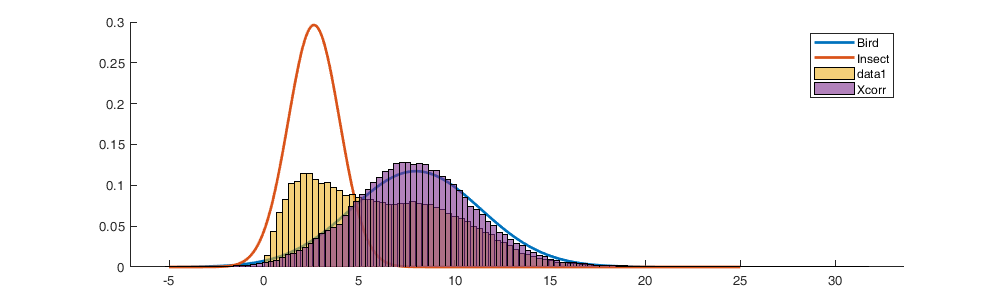

isnanv_a=isnan(v_a);
X=abs(v_a(~isnanv_a));
alpha = reshape([dc.bird],size(v_a));
alpha0=alpha(~isnanv_a);
subs=randi(numel(X),100000,1);
pBsX = pdfB .* normpdf(X(subs),(1-alpha0(subs)).* gmfit.mu(2,1) + alpha0(subs)*as, sqrt(gmfit.Sigma(1,1,2)));
pBsX = pBsX./sum(pBsX,2);
[~,id] = min(abs(cumsum(pBsX,2) - rand(numel(X(subs)),1)),[],2);
Xcorr = as(id)+median(diff(as))*(rand(size(id'))-.5);

figure('position',[0 0 1000 300]); hold on;
plot(as,pdfB,'DisplayName','Bird','linewidth',2);
plot(as,pdfI,'DisplayName','Insect','linewidth',2);
histogram(X(subs),100,'Normalization','pdf')
histogram(Xcorr,100,'Normalization','pdf')
legend()

## Apply model to the dataset

% r = 200; % ratio of correlation between vertical and time: 1 => 200m = 5minutes
% [X,Y]=meshgrid(linspace(1,r*25,25),1:numel(dc(i_d).time));

for i_d=1:numel(dc)
    % Compute insect proportion
    tmp1 = repmat(ti(:,i_d),1,25).*reshape(pdf(gm1,[reshape(abs(v_a(:,:,i_d)),[],1) reshape(dc(i_d).sd_vvp2,[],1)]),size(v_a(:,:,i_d)));
    tmp2 = (1-repmat(ti(:,i_d),1,25)).*reshape(pdf(gm2,[reshape(abs(v_a(:,:,i_d)),[],1) reshape(dc(i_d).sd_vvp2,[],1)]),size(v_a(:,:,i_d)));
    dc(i_d).bird = tmp1 ./(tmp1+tmp2);
    
    % Interpolate the insect/bird ratio when dens3 exist but not sd_vvp/u/v
    idp = ~isnan(dc(i_d).dens3) & isnan(dc(i_d).bird);
    %     Fbird = scatteredInterpolant(X(~isnan(dc(i_d).bird)), Y(~isnan(dc(i_d).bird)), dc(i_d).bird(~isnan(dc(i_d).bird)),'nearest','nearest');
    %     dc(i_d).bird(idp) = Fbird(X(idp), Y(idp));
    Fbird = fillmissing(dc(i_d).bird,'nearest',2);
    Fbird = fillmissing(Fbird,'nearest',1);
    dc(i_d).bird(idp) = Fbird(idp);
    
    % Separate Insect from weather
    dc(i_d).insect=(1-dc(i_d).bird).*funratio(fitresult{i_d}.A1,fitresult{i_d}.m1,fitresult{i_d}.s1,fitresult{i_d}.a1,fitresult{i_d}.A2,fitresult{i_d}.m2,fitresult{i_d}.s2,fitresult{i_d}.a2,datenum(dc(i_d).time-datetime(2018,1,1)))';
    % imagesc(dc(i_d).insect','AlphaData',~isnan(dc(i_d).insect'))
    
    % Correct density by removing the
    dc(i_d).dens4 = dc(i_d).dens3 .* dc(i_d).bird;
    
    % Compute airspeed component (after interpolation so can't use v_a)
    airspeed_u = dc(i_d).u-real(dc(i_d).ws);
    airspeed_v = dc(i_d).v-imag(dc(i_d).ws);
    airspeed_l2 = sqrt(airspeed_u.^2 + airspeed_v.^2);
    
    % OLD
    % Compute the correction factor
    %cc = speed_corr(airspeed_l2, dc(i_d).insect)
    % apply to each component
    %dc(i_d).u2 = airspeed_u.*cc./airspeed_l2 + dc(i_d).windu;
    %dc(i_d).v2 = airspeed_v.*cc./airspeed_l2 + dc(i_d).windv;
    
    % find nan to reduce time
    idnan = ~(isnan(airspeed_l2(:)) | isnan(dc(i_d).insect(:)));
    
    % Build the pdf of the posteriori distribution of airspeed
    pBsX = pdfB .* normpdf(airspeed_l2(idnan),(1-dc(i_d).bird(idnan)).* gmfit.mu(2,1) + dc(i_d).bird(idnan)*as, sqrt(gmfit.Sigma(1,1,2)));
    pBsX = pBsX./sum(pBsX,2);
    % Sample randomly in the cdf
    [~,id] = min(abs(cumsum(pBsX,2) - rand(sum(idnan),1)),[],2);
    
    % reshape the value
    airspeed_l2_corr=nan(size(airspeed_l2));
    airspeed_l2_corr(idnan) = as(id)+median(diff(as))*(rand(size(id'))-.5);
    % Recompute the groundspeed components
    dc(i_d).ub = airspeed_u.*airspeed_l2_corr./airspeed_l2 + real(dc(i_d).ws);
    dc(i_d).vb = airspeed_v.*airspeed_l2_corr./airspeed_l2 + imag(dc(i_d).ws);
    
    % Same for insect
    pIsX = pdfI .* normpdf(airspeed_l2(idnan),dc(i_d).bird(idnan).* gmfit.mu(1,1) + (1-dc(i_d).bird(idnan))*as, sqrt(gmfit.Sigma(1,1,1)));
    pIsX = pIsX./sum(pIsX,2);
    [~,id] = min(abs(cumsum(pIsX,2) - rand(sum(idnan),1)),[],2);
    airspeed_l2_corr=nan(size(airspeed_l2));
    airspeed_l2_corr(idnan) = as(id)+median(diff(as))*(rand(size(id'))-.5);
    % Recompute the groundspeed components
    dc(i_d).ui = airspeed_u.*airspeed_l2_corr./airspeed_l2 + real(dc(i_d).ws);
    dc(i_d).vi = airspeed_v.*airspeed_l2_corr./airspeed_l2 + imag(dc(i_d).ws);
end

figure('position',[0 0 800 450]); hold on;
histogram(sqrt( ([dc.ub] - real([dc.ws])).^2 + ([dc.vb] - imag([dc.ws])).^2),100,'EdgeColor','none','DisplayName','after correction')
histogram(sqrt( ([dc.ui] - real([dc.ws])).^2 + ([dc.vi] - imag([dc.ws])).^2),100,'EdgeColor','none','DisplayName','after correction')
histogram(sqrt( ([dc.u] - real([dc.ws])).^2 + ([dc.v] - imag([dc.ws])).^2),100,'EdgeColor','none','DisplayName','before correction')
f=ksdensity(abs(v_a(:)),as);
plot(as,pdfB./max(pdfB)*271200,'DisplayName','Bird','linewidth',2);
plot(as,pdfI./max(pdfI)*335700,'DisplayName','Insect','linewidth',2);

xlabel('Air speed [m/s]')
xlim([0 25]); box on;

### Export the data

% CleaningV(dc)

Save

% save('data/dc_corr','dc','start_date','end_date','quantity','-v7.3')
save('data/insect_removal','xi1','xi2','ft','gmfit','f_1','f_2','amplia','ampliall','amplir','amplit','fall','falt','fradar','ft','ftime','tmonth','ti','gm1','gm2','fitresult','funratio')

## Result

[G,day_num]=findgroups(datenum(dateshift(dc(1).time,'start','day','nearest')));
G2=repmat(G',1,25);

birdDENSmean=nan(numel(day_num),numel(dc));
birdDENSmean_OLD=birdDENSmean;
insectDENSmean = birdDENSmean;
birdMTRmean = birdDENSmean;
insectMTRmean = birdDENSmean;
weatherDENSmean = birdDENSmean;
birdMTRmean_OLD = birdDENSmean;
birdDIRmean=birdDENSmean;
insectDIRmean=birdDENSmean;
for i_d=1:numel(dc)
    % Figure of proportion
    %     propdenssum = splitapply(@nansum,dc(i_d).dens3(:).*dc(i_d).bird(:),G2(:));
    %     denssum = splitapply(@nansum,dc(i_d).dens3(:),G2(:));
    %     plot(day_num, propdenssum./denssum);
    %     datetick('x','keeplimits')
    
    birdDENSmean(:,i_d) = splitapply(@nanmean,nansum(dc(i_d).dens3 .* dc(i_d).bird .* .2,2),G');
    insectDENSmean(:,i_d) = splitapply(@nanmean,nansum(dc(i_d).dens3 .* dc(i_d).insect .* .2,2),G');
    weatherDENSmean(:,i_d) = splitapply(@nanmean,nansum(dc(i_d).dens3 .* (1-dc(i_d).bird-dc(i_d).insect) .* .2, 2),G');
    
    % /1000*60*60*5  :m/s -> km/hr + bird/km^3 -> bird/km^2
    tmp = dc(i_d).dens3 .* dc(i_d).bird  .* .2 .* sqrt(dc(i_d).ub.^2+dc(i_d).vb.^2);
    birdMTRmean(:,i_d)   = splitapply(@nanmean, nansum(tmp,2) /1000*60*60,G');
    assert(0==nansum(tmp(isnan(dc(i_d).vb(:))&isnan(dc(i_d).ub(:)))))
    V = splitapply(@nansum, tmp(:).*dc(i_d).vb(:),G2(:)) ./ splitapply(@nansum, tmp(:),G2(:));
    U = splitapply(@nansum, tmp(:).*dc(i_d).ub(:),G2(:)) ./ splitapply(@nansum, tmp(:),G2(:));
    birdDIRmean(:,i_d) = atan2d(V,U);
    tmp = dc(i_d).dens3 .* dc(i_d).insect.* .2 .* sqrt(dc(i_d).ui.^2+dc(i_d).vi.^2);
    insectMTRmean(:,i_d) = splitapply(@nanmean, nansum(tmp,2) /1000*60*60,G');
    assert(0==nansum(tmp(isnan(dc(i_d).vi(:))&isnan(dc(i_d).ui(:)))))
    V = splitapply(@nansum, tmp(:).*dc(i_d).vi(:),G2(:)) ./ splitapply(@nansum, tmp(:),G2(:));
    U = splitapply(@nansum, tmp(:).*dc(i_d).ui(:),G2(:)) ./ splitapply(@nansum, tmp(:),G2(:));
    insectDIRmean(:,i_d) = atan2d(V,U);
    tmp = dc(i_d).dens3 .* dc(i_d).insect.* .2 .* sqrt(dc(i_d).ui.^2+dc(i_d).vi.^2);
    weatherMTRmean(:,i_d) = splitapply(@nanmean, nansum(tmp,2) /1000*60*60,G');
    
    
    tmp = dc(i_d).dens3;
    tmp(sqrt(dc(i_d).u.^2 + dc(i_d).v.^2)<5)=0;
    tmp(dc(i_d).sd_vvp<2)=0;
    birdDENSmean_OLD(:,i_d) = splitapply(@nanmean,nansum(tmp .* .2,2),G');
    birdMTRmean_OLD(:,i_d) = splitapply(@nanmean,nansum(tmp.*.2 .* sqrt(dc(i_d).u.^2+dc(i_d).v.^2),2)/1000*60*60 ,G');
end

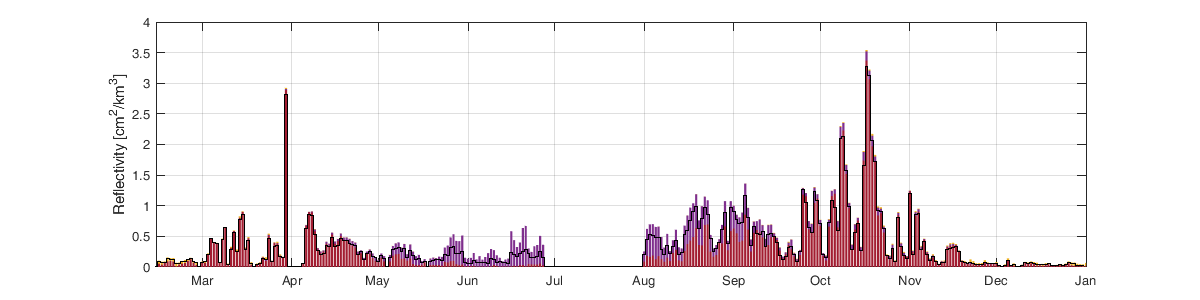

figure('position',[0 0 1200 300]); hold on;
b=bar(day_num, [nanmean(birdDENSmean,2) nanmean(insectDENSmean,2) nanmean(weatherDENSmean,2)]./11,'stacked');
b(1).FaceColor = [251 193 135]/255;b(2).FaceColor = [33 32 85]/255;
datetick('x','keeplimits'); xlim([737104 737426]); ylabel('Reflectivity [cm^2/km^3]');
box on; grid on;
% yyaxis right;
stairs(day_num-.5, nanmean(birdDENSmean_OLD,2)./11,'k');

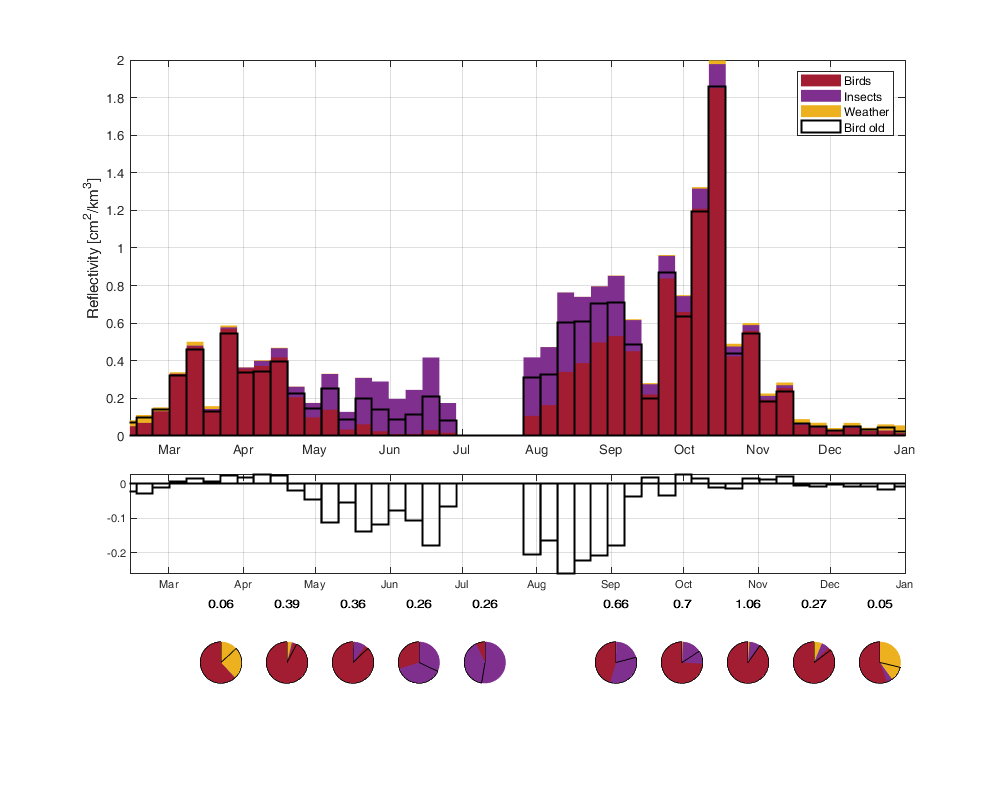

figure('position',[0 0 1000 800]);
gr_day = 7;
gr = repelem(1:1000,gr_day); gr=gr(1:length(day_num));
subplot(5,1,[1 3]);hold on;
b=bar(day_num(1:gr_day:end), splitapply(@nanmean,[nanmean(birdDENSmean,2) nanmean(insectDENSmean,2) nanmean(weatherDENSmean,2)],gr')./11,1,'stacked');
b(1).FaceColor = [251 193 135]/255; b(1).EdgeAlpha=0;
b(2).FaceColor = [33 32 85]/255; b(2).EdgeAlpha=0;
b(3).FaceColor = [0.9290 0.6940 0.1250]; b(3).EdgeAlpha=0;
b2=bar(day_num(1:gr_day:end),splitapply(@nanmean,nanmean(birdDENSmean_OLD,2),gr')./11,1,'k');
b2(1).FaceAlpha =0; b2(1).LineWidth=1.5;
% stairs(splitapply(@nanmean,day_num,gr)-gr_day/2, splitapply(@nanmean,nanmean(birdDENSmean_OLD,2),gr')./11,'k');
datetick('x','keeplimits'); xlim([737104 737426]); ylabel('Reflectivity [cm^2/km^3]');
legend('Birds','Insects','Weather','Bird old'); box on; grid on; %ylim([0 1])

subplot(5,1,4);hold on;
b2=bar(day_num(1:gr_day:end),(splitapply(@nanmean,nanmean(birdDENSmean,2),gr')-splitapply(@nanmean,nanmean(birdDENSmean_OLD,2),gr'))./11,1,'k');
b2(1).FaceAlpha =0; b2(1).LineWidth=1.5;
box on; grid on;datetick('x','keeplimits'); xlim([737104 737426]); 

subplot(5,1,5);hold on;
gr = month(day_num);
tt = splitapply(@nanmean,[nanmean(birdDENSmean,2) nanmean(insectDENSmean,2) nanmean(weatherDENSmean,2)],gr')./11;
tt2 = splitapply(@nanmean, nanmean(birdDENSmean_OLD,2),gr')./11;

for i=[2 3 4 5 6 8 9 10 11 12]
    subplot(5,12,48+i); 
    p=pie(tt(i,:)/nansum(tt(i,:)),{'','',''});
    p(1).FaceColor = [251 193 135]/255; p(1).EdgeAlpha=0; 
    p(3).FaceColor = [33 32 85]/255; p(3).EdgeAlpha=0; 
    p(5).FaceColor = [0.9290 0.6940 0.1250]; p(5).EdgeAlpha=0; 
    hold on
    p2 = pie(tt2(i,:)./nansum(tt(i,:)),{''});
    p2(1).FaceAlpha=0;
    axis equal
    title(num2str(round(nansum(tt(i,:)),2)))
end

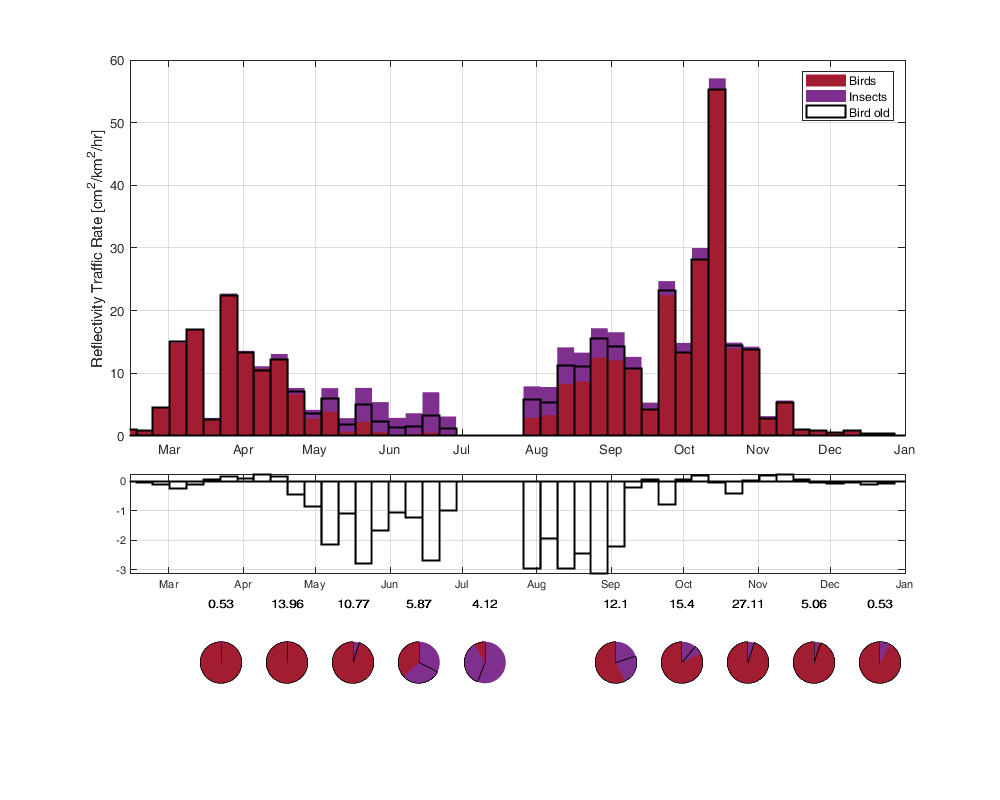

figure('position',[0 0 1000 800]);
gr_day = 7;
gr = repelem(1:1000,gr_day); gr=gr(1:length(day_num));
subplot(5,1,[1 3]);hold on;
b=bar(day_num(1:gr_day:end), splitapply(@nanmean,[nanmean(birdMTRmean,2) nanmean(insectMTRmean,2)],gr')./11,1,'stacked');
b(1).FaceColor = [251 193 135]/255; b(1).EdgeAlpha=0;
b(2).FaceColor = [33 32 85]/255; b(2).EdgeAlpha=0;
%b(3).FaceColor = [0.9290 0.6940 0.1250]; b(3).EdgeAlpha=0;
b2=bar(day_num(1:gr_day:end),splitapply(@nanmean,nanmean(birdMTRmean_OLD,2),gr')./11,1,'k');
b2(1).FaceAlpha =0; b2(1).LineWidth=1.5;
% stairs(splitapply(@nanmean,day_num,gr)-gr_day/2, splitapply(@nanmean,nanmean(birdDENSmean_OLD,2),gr')./11,'k');
datetick('x','keeplimits'); xlim([737104 737426]); ylabel('Reflectivity Traffic Rate [cm^2/km^2/hr]');
legend('Birds','Insects','Bird old'); box on; grid on; %ylim([0 1])

subplot(5,1,4);hold on;
b2=bar(day_num(1:gr_day:end),(splitapply(@nanmean,nanmean(birdMTRmean,2),gr')-splitapply(@nanmean,nanmean(birdMTRmean_OLD,2),gr'))./11,1,'k');
b2(1).FaceAlpha =0; b2(1).LineWidth=1.5;
box on; grid on;datetick('x','keeplimits'); xlim([737104 737426]); 

subplot(5,1,5);hold on;
gr = month(day_num);
tt = splitapply(@nanmean,[nanmean(birdMTRmean,2) nanmean(insectMTRmean,2)],gr')./11;
tt2 = splitapply(@nanmean, nanmean(birdMTRmean_OLD,2),gr')./11;

for i=[2 3 4 5 6 8 9 10 11 12]
    subplot(5,12,48+i); 
    p=pie(tt(i,:)/nansum(tt(i,:)),{'',''});
    p(1).FaceColor = [251 193 135]/255; p(1).EdgeAlpha=0; 
    p(3).FaceColor = [33 32 85]/255; p(3).EdgeAlpha=0; 
    hold on
    p2 = pie(tt2(i,:)./nansum(tt(i,:)),{''});
    p2(1).FaceAlpha=0;
    axis equal
    title(num2str(round(nansum(tt(i,:)),2)))
end